    skok = 10;
    liczba_probek = 20;
    [errors1, indexes, my_results] = compute_error(liczba_probek, skok, @generator_1, @Jacobi_2);

solving ...
done
Elapsed time is 0.130188 seconds.


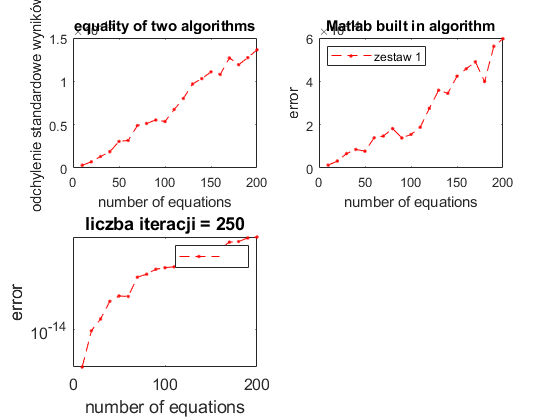

solving ...
done
Elapsed time is 0.006658 seconds.


     
    figure('Name','Porownanie algorytmow','NumberTitle','off');
    ax1 = subplot(2, 2, 3);
    semilogy(ax1, indexes, errors1, 'r--.');
    xlabel(ax1, 'number of equations');
    ylabel(ax1, 'error');
    title(ax1, 'liczba iteracji = 250');
    legend(ax1, '')
    ax1 = gca;
    ax1.FontSize = 12;

    compare_with_default(liczba_probek, skok, my_results, @generator_1);